## Propagación de errores

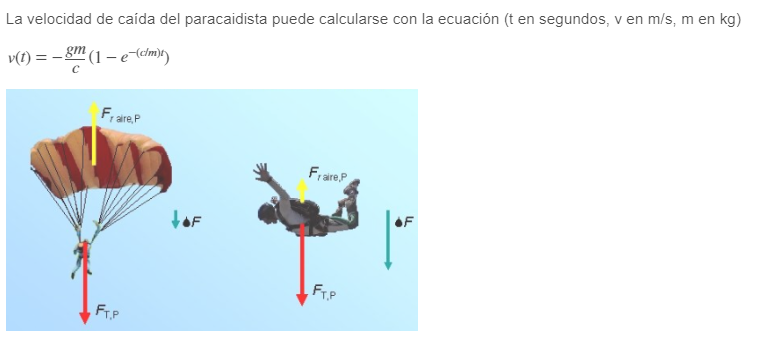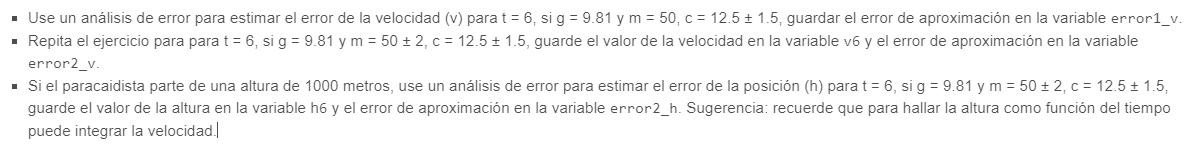

syms g m c t
v = (-g*m / c)*(1 - exp(-c*t / m))

$$v = \frac{g\,m\,\left({\mathrm{e}}^{-\frac{c\,t}{m}}-1\right)}{c}$$

t1 = 6;
g1 = 9.81;
m1 = 50;
c1 = 12.5;

error_c = 1.5;
dv_dc= diff(v,c)

$$dv\_dc = -\frac{g\,t\,{\mathrm{e}}^{-\frac{c\,t}{m}}}{c}-\frac{g\,m\,\left({\mathrm{e}}^{-\frac{c\,t}{m}}-1\right)}{c^{2}}$$

dv = abs(dv_dc)*error_c

$$dv = \frac{3\,\left|\frac{g\,t\,{\mathrm{e}}^{-\frac{c\,t}{m}}}{c}+\frac{g\,m\,\left({\mathrm{e}}^{-\frac{c\,t}{m}}-1\right)}{c^{2}}\right|}{2}$$

error1_v= double( subs(dv, {t,g,m,c}, {t1,g1,m1,c1}))

error1_v =    2.082111754732684


v6 = double(subs(v,{t,g,m,c},{6,9.81,50,12.5}))

v6 =  -30.484372515775615



error_m = 2;
dv_dm = diff(v,m)

$$dv\_dm = \frac{g\,\left({\mathrm{e}}^{-\frac{c\,t}{m}}-1\right)}{c}+\frac{g\,t\,{\mathrm{e}}^{-\frac{c\,t}{m}}}{m}$$

dv = abs(dv_dm) * error_m + abs(dv_dc) * error_c

$$dv = 2\,\left|\frac{g\,\left({\mathrm{e}}^{-\frac{c\,t}{m}}-1\right)}{c}+\frac{g\,t\,{\mathrm{e}}^{-\frac{c\,t}{m}}}{m}\right|+\frac{3\,\left|\frac{g\,t\,{\mathrm{e}}^{-\frac{c\,t}{m}}}{c}+\frac{g\,m\,\left({\mathrm{e}}^{-\frac{c\,t}{m}}-1\right)}{c^{2}}\right|}{2}$$

error2_v = double( subs(dv, {t,g,m,c}, {t1,g1,m1,c1}))

error2_v =    2.776149006310245


h0 = 1000;
h = int(v, t) - subs(int(v, t), 0) + h0

$$h = \frac{g\,m^{2}}{c^{2}}-\frac{g\,m\,\left(m\,{\mathrm{e}}^{-\frac{c\,t}{m}}+c\,t\right)}{c^{2}}+1000$$

h6 = double( subs(h,{t,g,m,c},{t1,g1,m1,c1}))

h6 =      8.864974900631024e+02


dh_dm = diff(h,m);
dh_dc = diff(h,c);

dh = abs(dh_dm)*error_m + abs(dh_dc)*error_c

$$dh = \begin{array}{l} 2\,\left|\frac{g\,\sigma_{1}}{c^{2}}-\frac{2\,g\,m}{c^{2}}+\frac{g\,m\,\left(\sigma_{2}+\frac{c\,t\,\sigma_{2}}{m}\right)}{c^{2}}\right|+\frac{3\,\left|\frac{2\,g\,m^{2}}{c^{3}}+\frac{g\,m\,\left(t-t\,\sigma_{2}\right)}{c^{2}}-\frac{2\,g\,m\,\sigma_{1}}{c^{3}}\right|}{2}\\ \mathrm{where}\\ \sigma_{1}=m\,\sigma_{2}+c\,t\\ \sigma_{2}={\mathrm{e}}^{-\frac{c\,t}{m}} \end{array}$$

error2_h = double(subs(dh,{t,g,m,c},{t1,g1,m1,c1}))

error2_h =    7.055805564662625
